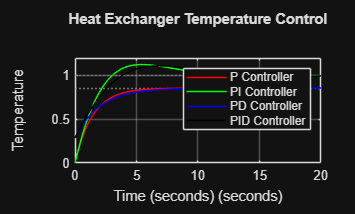

clc;
clear;
close all;

%% Heat Exchanger Model
K = 2;          % Process gain
tau = 10;       % Time constant

num = K;
den = [tau 1];
G = tf(num,den);

%% Controller Parameters
Kp = 3;
Ki = 1;
Kd = 2;

%% P Controller
C_P = pid(Kp,0,0);
sys_P = feedback(C_P*G,1);

%% PI Controller
C_PI = pid(Kp,Ki,0);
sys_PI = feedback(C_PI*G,1);

%% PD Controller
C_PD = pid(Kp,0,Kd);
sys_PD = feedback(C_PD*G,1);

%% PID Controller
C_PID = pid(Kp,Ki,Kd);
sys_PID = feedback(C_PID*G,1);

%% Step Response Comparison
figure;
step(sys_P,'r',sys_PI,'g',sys_PD,'b',sys_PID,'k',20);
legend('P Controller','PI Controller','PD Controller','PID Controller');
title('Heat Exchanger Temperature Control');
xlabel('Time (seconds)');
ylabel('Temperature');
grid on;


%% Performance Parameters
disp('P Controller Performance');

P Controller Performance


stepinfo(sys_P)

ans = struct with fields:
         RiseTime: 3.1386
    TransientTime: 5.5887
     SettlingTime: 5.5887
      SettlingMin: 0.7753
      SettlingMax: 0.8566
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8566
         PeakTime: 10.4603



disp('PI Controller Performance');

PI Controller Performance


stepinfo(sys_PI)

ans = struct with fields:
         RiseTime: 2.2214
    TransientTime: 11.2223
     SettlingTime: 11.2223
      SettlingMin: 0.9201
      SettlingMax: 1.1252
        Overshoot: 12.5164
       Undershoot: 0
             Peak: 1.1252
         PeakTime: 5.3946



disp('PD Controller Performance');

PD Controller Performance


stepinfo(sys_PD)

ans = struct with fields:
         RiseTime: 3.7946
    TransientTime: 7.8241
     SettlingTime: 7.0134
      SettlingMin: 0.7745
      SettlingMax: 0.8568
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8568
         PeakTime: 14.6444



disp('PID Controller Performance');

PID Controller Performance


stepinfo(sys_PID)

ans = struct with fields:
         RiseTime: 2.9115
    TransientTime: 13.1632
     SettlingTime: 12.6831
      SettlingMin: 0.9048
      SettlingMax: 1.1103
        Overshoot: 11.0280
       Undershoot: 0
             Peak: 1.1103
         PeakTime: 6.8157


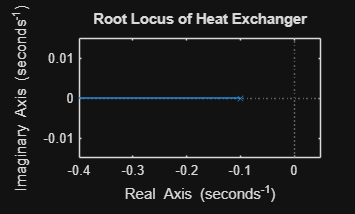

figure
rlocus(G)
title('Root Locus of Heat Exchanger')

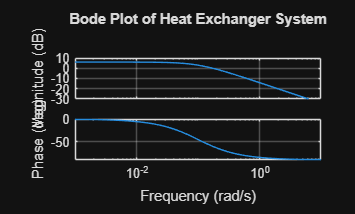

figure
bode(G)
grid on
title('Bode Plot of Heat Exchanger System')